`In the name of God`

# Blind Source Separation

## HW#3

**Maryam Riazi**

**810197518**

### Assumptions

s1 = unifrnd(-3,3,1,1000);
s2 = unifrnd(-2,2,1,1000);

s1 = s1-mean(s1);
s2 = s2-mean(s2);

A = [1 -2
    2 -1
    3 -2];

S = [s1
    s2];

X = A*S;
x1 = X(1,:);
x2 = X(2,:);
x3 = X(3,:);

### Question1.

figure
scatter3(x1,x2,x3,'red','x')
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
title('Scatter Plot of X')
Rx = X*transpose(X)
[U,D] = eig(Rx)
U = flip(U,2)
D = flip(flip(D,2))

### Question2.

u1 = U(:,1);
u2 = U(:,2);
u3 = U(:,3);

#### A)

transpose(u3)*X

As it is shown (u3)' * X is somehow equal to a zeros vector!

#### B)

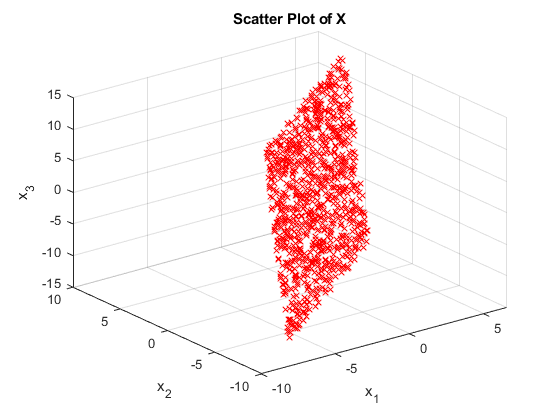

transpose(u3)*A

As it is shown (u3) * A is somehow equal to a zeros vector!

#### C)

Now we want to find the C matrix which creates A matrix by multiplying to U vector:


$$A=\left\lbrack \begin{array}{cc}
1 & -2\\
2 & -1\\
3 & -2
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
u_1  & u_2 
\end{array}\right\rbrack \times C$$


C = [u1 u2]\A

Rx = 	1.0e+04 *

    0.8137    0.8487    1.4029
    0.8487    1.3226    2.0464
    1.4029    2.0464    3.1962


A_test = [u1 u2]*C

U =     0.1961    0.9141    0.3549
    0.7845   -0.3634    0.5026
   -0.5883   -0.1798    0.7884


D = 	1.0e+04 *

   -0.0000         0         0
         0    0.2003         0
         0         0    5.1322


As you could see the C matrix which we found, works correctly!

### Question3.

Z = [u1 u2]'*X;

U =     0.3549    0.9141    0.1961
    0.5026   -0.3634    0.7845
    0.7884   -0.1798   -0.5883


z1 = Z(1,:);

D = 	1.0e+04 *

    5.1322         0         0
         0    0.2003         0
         0         0   -0.0000


z2 = Z(2,:);

figure
scatter(z1,z2,'black','o')
xlabel('z_1')
ylabel('z_2')
xlim([-20 20])

ans = 	1.0e+-14 *

    0.0888    0.2665   -0.6217   -0.1776    0.2665    0.6689   -0.1776   -0.3553    0.8438    0.5329   -0.6217   -0.0888    0.8438    0.6661    0.3553   -0.4441    0.3553    0.0444    0.0666    0.6994   -0.4441    0.0888    0.3109   -0.2665    0.0777   -0.0888         0   -0.6550   -0.2220    0.4219    0.2665         0    0.6217   -0.5329   -0.2220    0.5218    0.0444    0.7161   -0.5218         0    0.0444   -0.0444   -0.3997    0.1554    0.4441    0.1776    0.5329   -0.4108    0.7994   -0.5773


ylim([-20 20])
title('Signal After PCR Algorithm')

Now we are going to do whitening algorithm on signals:

White_Z = D(1:2,1:2)^(-0.5)*Z; %ignoring the third eigenvalue

ans = 	1.0e+-14 *

   -0.0666   -0.3553


white_z1 = White_Z(1,:);
white_z2 = White_Z(2,:);

figure
scatter(white_z1,white_z2,'blue','x')

C =     3.7251   -2.7890
   -0.3521   -1.1052


xlabel('z_1')

A_test =     1.0000   -2.0000
    2.0000   -1.0000
    3.0000   -2.0000


ylabel('z_2')
title('Whitened Signal')

### Question4.

#### A)

[Q,G,V] = svd(X)
rank(X)

Remember that one of our eigenvalues was zero which means the that matrix is dependent only on two of them.

Consequently when one of our eigen vectors is dependent on the other two eigen vectors, the matrix rank will be 2!!

#### B)

U
-Q

As it is shown above, Both U and Q have same columns and surprisingly the columns are $R_X$ eigenvectors!!

#### C)

pure_G = G(1:3,1:3);
pure_G.^2
D

After removing the zero matrix (using G(1:3,1:3) ) 

$G=S\;\left(\textrm{in}\;\textrm{SVD}\right)$ and $D=\Lambda$ $\Rightarrow$ ${g_i }^2 =d_i$.

#### D)

White_Z
transposed_V = transpose(V);
V1 = transposed_V(1:2,:)

Yes! This is the power of LINEAR ALGEBRA. It is unbelievable but as you could see above and according to below equations, White_Z and first two rows of transposed V are the same...

$Z={\Lambda_1 }^{-\frac{1}{2}} {\;U_1 }^T X$ , $V_1 ={\Lambda_1 }^{-\frac{1}{2}} {\;U_1 }^T X$


$$\Rightarrow Z=V_1$$


### Question5.

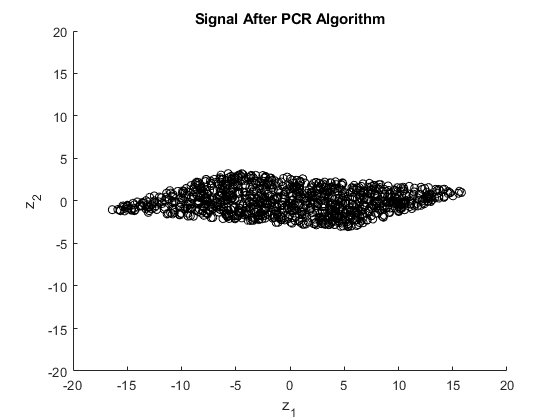

F = transpose(White_Z'\S')

S_test = F*White_Z
S

According to above results:

span (the first two rows of matrix V) = the space that S belongs to

Hence, S should be orthogonal to the remained rows of V matrix.

### Question6.

All I do was creating a loop in which in every iteration I sum up the E (energy) and diagonal D elements untill it goes more than 90 percent of total energy.

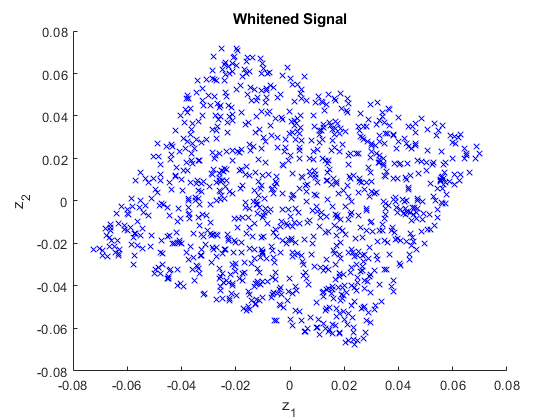

E = 0;
Et = sum(sum(D));

for i = 1:3
    E = E+D(i,i);
    if E >= 0.9*Et
        Z_90percent = D(1:i,1:i)*U(:,1:i)'*X;
        break;

F =    49.1024  -24.4802
  -15.6450  -32.6963


S_test =     1.3933    2.2777   -1.6203   -2.2984   -1.7255   -0.9759   -1.3534    2.4890   -2.7681    0.4801   -2.0985    1.9545   -2.0706   -0.0627    2.9200   -0.9435   -2.7935   -1.7940   -0.6889   -1.0739   -1.6983    2.5408    1.0232    2.6967   -0.4481    2.5661   -3.0409    0.5859    1.7305   -1.6780    2.5189    1.5036    1.8828    0.3648    1.6796   -1.1017   -1.7352   -1.2016    0.4312    1.9035   -1.3332   -0.6606    2.0964    0.6125    2.8712   -1.8537    1.8873    0.9792   -1.5822   -0.2212
   -0.5276   -0.7697    1.8982    0.8267   -0.3933   -1.6515    0.8922    0.5032   -1.7506   -1.5640    1.8804   -0.0588   -1.9564   -1.8307   -1.4825    1.5279   -0.1827    0.1974   -0.0682   -1.7749    1.5446   -0.8918   -0.9698    0.3308   -0.1425   -0.5728    0.5764    1.7068    0.4357   -0.9147   -1.2253   -0.2895   -1.9370    1.4587    0.3944   -1.2316    0.0337   -1.8307    1.4027   -0.2743    0.1460    0.2214    0.6756   -0.5605   -1.7331   -0.2206   -1.8546    0.9070   -1.8940

S =     1.3933    2.2777   -1.6203   -2.2984   -1.7255   -0.9759   -1.3534    2.4890   -2.7681    0.4801   -2.0985    1.9545   -2.0706   -0.0627    2.9200   -0.9435   -2.7935   -1.7940   -0.6889   -1.0739   -1.6983    2.5408    1.0232    2.6967   -0.4481    2.5661   -3.0409    0.5859    1.7305   -1.6780    2.5189    1.5036    1.8828    0.3648    1.6796   -1.1017   -1.7352   -1.2016    0.4312    1.9035   -1.3332   -0.6606    2.0964    0.6125    2.8712   -1.8537    1.8873    0.9792   -1.5822   -0.2212
   -0.5276   -0.7697    1.8982    0.8267   -0.3933   -1.6515    0.8922    0.5032   -1.7506   -1.5640    1.8804   -0.0588   -1.9564   -1.8307   -1.4825    1.5279   -0.1827    0.1974   -0.0682   -1.7749    1.5446   -0.8918   -0.9698    0.3308   -0.1425   -0.5728    0.5764    1.7068    0.4357   -0.9147   -1.2253   -0.2895   -1.9370    1.4587    0.3944   -1.2316    0.0337   -1.8307    1.4027   -0.2743    0.1460    0.2214    0.6756   -0.5605   -1.7331   -0.2206   -1.8546    0.9070   -1.8940    1

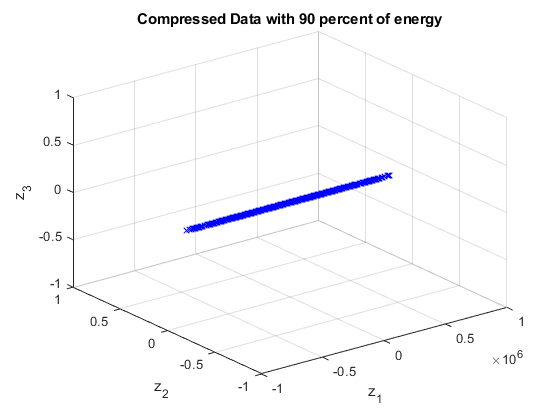

    end
end
figure
scatter3(Z_90percent,zeros([1,length(Z_90percent)]),zeros([1,length(Z_90percent)]),'blue','x')
xlabel('z_1')
ylabel('z_2')
zlabel('z_3')
title('Compressed Data with 90 percent of energy')